# 03 Aliasing, filtrace ve spektru

## Úvod

### **Aliasing**

V případě nedodržení vzorkovacího teorému při digitalizaci signálu, kdy frekvenční komponenty vzorkovaného signálu $f_{\max } \ge \frac{f_s }{2}$, dojde k nejednoznačnému vzorkování. Harmonická funkce s frekvencí $f_k$ nabývá stejných hodnot v časech vzorkování $t_n$ jako funkce s frekvencí ${f_s -f}_k$, tj. $x_{f_k } \left\lbrack t_n \right\rbrack =x_{{f_s -f}_k } \left\lbrack t_n \right\rbrack$. Pokud tedy vzorkovaný signál obsahuje složku o frekvenci $>\frac{f_s }{2}$, přičítá se ke složce $<\frac{f_s }{2}$ a dále se zrcadlí. Tomuto nežádoucímu jevu se říká **aliasing**. V technické praxi je nutno analogový signál před vzorkováním (digitalizací) frekvenčně omezit dolní propustí s mezním kmitočtem $f_0 <\frac{f_s }{2}$. Nedodržení vzorkovacího teorému vede ke zkreslení signálu a jeho nepoužitelnosti.

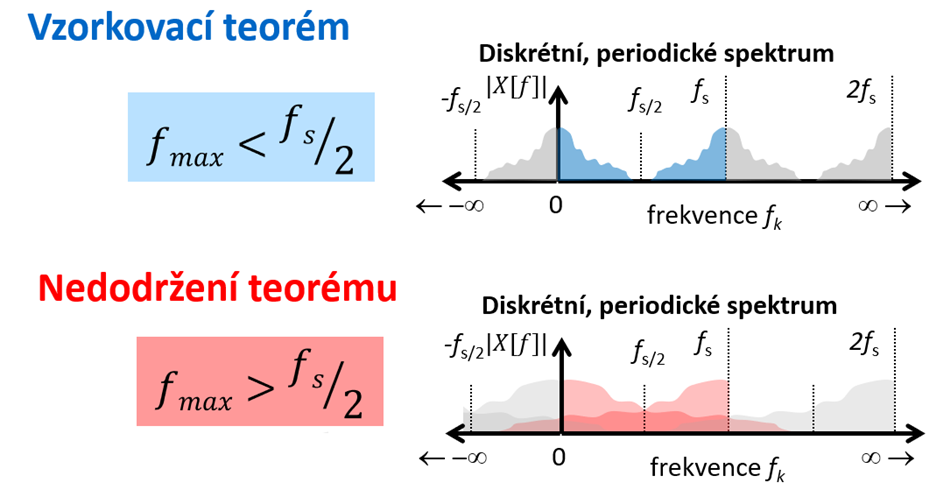

Pozn.:

- V praxi se většinou volí $f_{\max } \le \frac{f_s }{3}$ nebo, častěji však výrazně nižšší. Záleží však na mnoha okolneostech, např. na strmosti hardwarového antialiasing filtru před A/D převodníkem.

- Aliasingu se ve speciálních případech využívá úmyslně, např. v radioelektronice, kde vysokofrekvenční signál podvzorkováním dostaneme vlivem aliasingu do nízkofrekvenčního pásma (demodulace).

- Můžete se podívat na [video](https://www.youtube.com/watch?v=v7qjeUFxVwQ) o aliasingu.

### Filtrace ve spektru

Filtrace je zákládní metodou úravy signálu. Filtrací můžeme ponechat/zesílit určitou část frekvenčního spektra, která pro nás nese užitečnou informaci, nebo naopak potlačit frekvenční složky, které jsou neužitečné a rušivé. 

Ačkoli fitlrům budou věnovány samostané přednášky a cvičení později, proncipiálně se bude jednat o techniky, ktyry potlačí nežádoucí frekvenční pásma (dolní, horní, pásmová propust nebo zádrž). Spektrálně se však jedná o potlačení/odstranění frekvenčních složek v signálu.

#### Nulování spektrálních čar

Ze signálu nejprve spočteme frekvenční spektrum a určíme frekvenční osu, tj. frekvence harmonických složek. Následně nalezneme harmonické složky, které chceme ze signálu odfiltrovat a změníme jejich hodnotu na nulu. Tím se harmonická složka neuplatní (odstraní) při rekonstrukci signálu inverzní Fourierovou transformací. U disrétních signálů anesmíme zapomínat, že se frekvenční složky reálných signálů se ve spktru zrcadlí kolem $\frac{f_s }{2}$. Při nulování harmonických složek $f$ tedy musíme nulovat na obou stranách spektra, tj. $X\left\lbrack f\right\rbrack =0$ pro$f$ a $f_s -f$.

Výhodou tohoto přístupu je jednoduchost implementace, avšak nevýhod je více. Filtrace nelze provádět v reálném čase a je závislá na počtu vzorků filtrovaného signálu (počet harmonických složek odpovídá počtu vzorků signálu $K=N$), tedy i frekvenčním rozlišení spektra (malé rozlišení pro malé $N$). Později si ukážeme, že nulování spetrálních čar by odpovídalo idelnímu filtru s nekonečnou strmostí, to ale v časové oblasti vede k dlouhé impulzní odezvě (zvlnění za impulzy, tranzienty, skokokovými změnami). V digitálním zpracování pomocí DFT periodizujeme finitní signál, na začátku a konci signálu tedy dochází k nespojitosti a zvlnění téměř vždy.

Např. v dnešním cvičení budeme filtrovat $50$ Hz, resp. úzké pásmo $49-51$ Hz. Při malém počtu vzorků, tj. i malém spektrálním rozlišení, nemusíte dokázat filtrovat přes prostou indexaci spektrálních čar X`(f<=49 & f<=51)=0`, protože spektrální čáry vyjdou mimo rozsah diskrétnách harmonických frekvencí. 

## **Řešení:**

### **Aliasing**

#### **Podvzorkování sinusoidy**

Generujte harmonický průběh s pracovním kmitočtem $f_0 =5$ Hz a fázovým posunem $\phi =\frac{\pi }{4}$ vzorkovaný následujícími vzorkovacími kmitočty $f_s$ (simuljte vzorkování s rozdílnou frekvencí).

- $f_{\textrm{s1}} =\;\;\;10\cdot f_0 =\;\;\;\;\;50$ Hz,

- $f_{\textrm{s2}} =\;\;\;\;\;3\cdot f_0 \;=\;\;\;\;15$ Hz,

- $f_{\textrm{s3}} =1,2\cdot \;f_0 \;=\;\;\;\;\;\;6$ Hz.

Průběh vygenerujte se stejnou délkou $T=5$ s.

f0 = 5;
phi = pi/4;
T = 5;

fs10 = 10*f0

fs10 = 50

t10 = 0:1/fs10:T-1/fs10;
y10 = sin(2*pi*f0*t10+phi);
fs3 = 3*f0

fs3 = 15

t3 = 0:1/fs3:T-1/fs3;
y3 = sin(2*pi*f0*t3+phi);

fs1_2 = 1.2*f0

fs1_2 = 6

t1_2 = 0:1/fs1_2:T-1/fs1_2;
y1_2 = sin(2*pi*f0*t1_2+phi);


**V subplot 3x1 zobrazte všechny signály, zvýrazněte vzorky symbolem (**`'x'`**). Popište osy, do titulku vložte hodnoty použitých **`fs`**. Poměr kmitočtů zobrazte jako **`r=fs/fo`**.**

**Zobrazte harmonický signál o **$f_0$** pro různá **$f_s$** simulující splnění vzorkovacího teorému.**

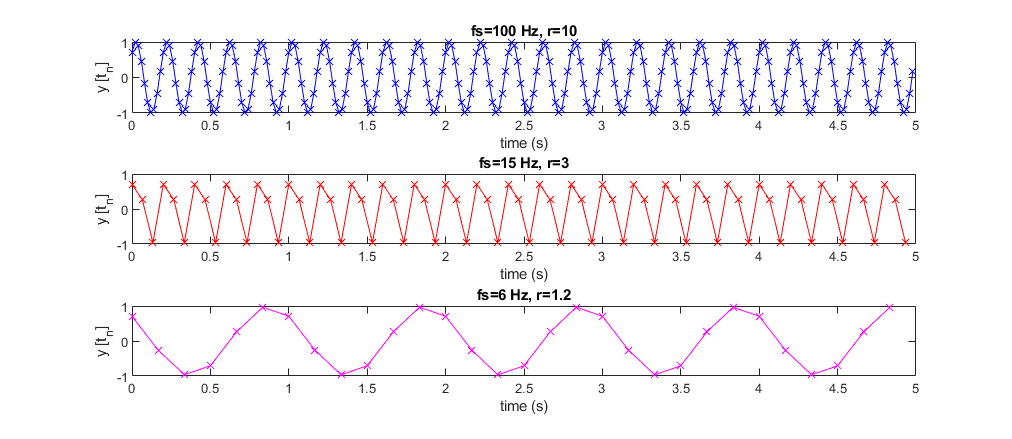

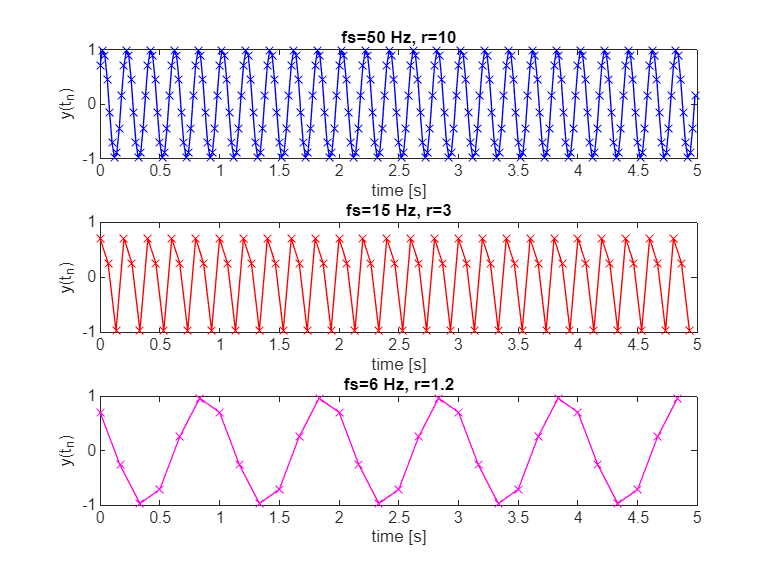

figure
subplot(3,1,1)
plot(t10,y10,Marker="x", color="b")
title("fs=50 Hz, r=10")
xlabel("time [s]")
ylabel("y(t_n)")

subplot(3,1,2)
plot(t3,y3, Marker="x", Color="r")
title("fs=15 Hz, r=3")
xlabel("time [s]")
ylabel("y(t_n)")

subplot(3,1,3)
plot(t1_2,y1_2, Marker="x", Color=[1 0 0.9])
title("fs=6 Hz, r=1.2")
xlabel("time [s]")
ylabel("y(t_n)")

**Zobrazte přes sebe do jednoho grafu průběhy pro r=10 a r=1,2.**

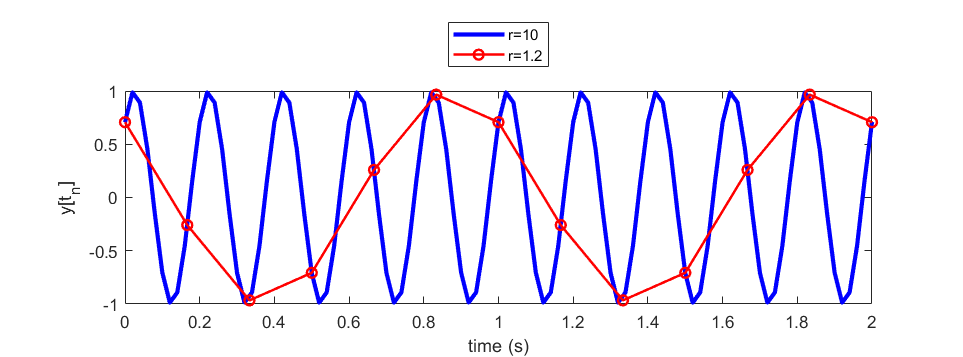

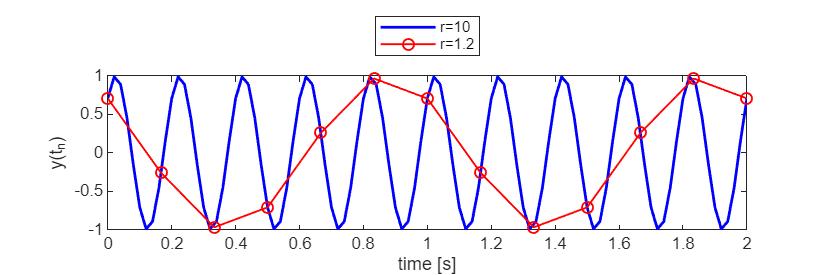

figure('Position',[0 0 600 200])
idx = t10<=2;
idx2 = t1_2<=2;
plot(t10(idx),y10(idx),"b", LineWidth=1.5)
hold on
plot(t1_2(idx2),y1_2(idx2), Color="r", Marker="o", LineWidth=1)
hold off
legend('r=10','r=1.2',Location='northoutside')
xlabel("time [s]")
ylabel("y(t_n)")

**Odpovězte na otázky:**

- **Pro který případ není splněn vzorkovací kmitočet?**

            pro případ kdy se fs = 1.2*f0

- **Pro vygenerovaný harmonický signál s **$f_0$** a vzorkovací kmitočet **$f_s$**, který jste napsali v předchozí odpovědi, spočítejte magnitodové spektrum a určete dominantní kmitočet **${f_0 }^{\prime }$** na stupnici 0 až **$\frac{f_s }{2}$** Hz (tj. určete z grafu první kmitočet s nejvyšší amplitudou)**

N = fs1_2*T; 
Y = 1/N*fft(y1_2);
f = linspace(0,fs1_2-fs1_2/N,N);
disp(f(Y>0.1))

     1     5



disp(abs(Y(f == 1)))

    0.5000



           dominantní kmitočet je  $f_0$ = 1Hz s amplitudou 0.5

- **Spočtěte teoreticky frekvenci **${f_0 }^{\prime }$ **, kam se zrcadlí **$f_0$ **při nesplnění vzorkovacího teorému**

        
$${f_0 }^{\prime } =\frac{f_s }{2}-\textrm{abs}\left(\frac{f_s }{2}-f_0 \right)=3-\textrm{abs}\left(3-5\right)=3-2=1$$


            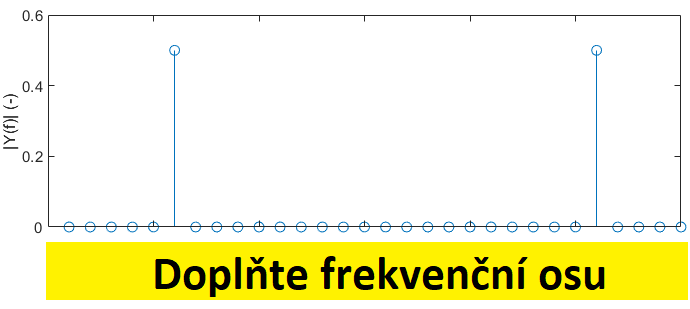

**Vypočtěte teoreticky hodnotu **${f_0 }^{\prime }$:

N = fs1_2*T; 
Y = 1/N*fft(y1_2);
f = linspace(0,fs1_2-fs1_2/N,N);
disp(f(Y>0.1))

     1     5



disp(abs(Y(f == 1)))

    0.5000



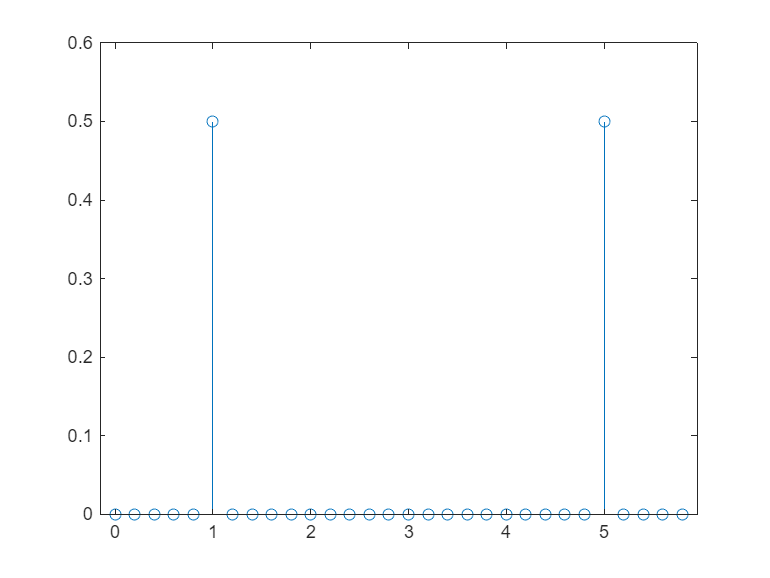

figure
stem(f,abs(Y))

**Odečtěte ze spektra:           **

${f_0 }^{\prime } =$**      1          Hz, s amplitudou |Y| = **`0.5`

### Filtrace ve spektru

Odstraníme síťové rušení 50±1 Hz a jeho vyšších harmonických složek $m\times \left(50\pm 1\right),m\in \left\lbrace 1,\;2,\;3,\;\ldotp \ldotp \ldotp \right\rbrace$. Ve spektru nahradíme odpovídající spektrální čáru nulovou amplitudou $X\left\lbrack f_k \right\rbrack =0$. Uvědomte si, že musíme nulovat spektrální čáry na obou stranách spektra, tj. $f$a $f_s -f$. Pro rekonstrukci signálu provedeme inverzní Fourierovu transformaci.

Nejprve si vyčistíme proměnné ve workspace a zavřeme všechny figury: 

clear all; % vymaže všechny proměné
close all; % zavře všechny figury

Pomocí funkce `load` si načtěte signál EKG uložený v `.txt` souboru, který obsahuje časovou řadu amplitud. 

EKG=load('ecg_hum_fs500Hz.txt');

Error using load
ecg_hum_fs500Hz.txt is not found in the current folder or on the MATLAB path, but exists in:
    C:\projects\cvut\zzs\ukol3

Change the MATLAB current folder or add its folder to the MATLAB path.

Na rozdíl od kontejneru `.mat`, textový soubor neobsahuje další metadata jako např. informace o vzorkovacím kmitočtu nebo o fyzikálních jednotkách. Vzorkovací kmitočet $f_s$ zde vyčtete z názvu souboru. Prozradím, že měřené jednotky jsou v **mV**.

fs=500; % vzorkovací kmitočet

Ze znalosti počtu vzorků signálu a vzorkovacího kmitočtu vytvořte časovou osu. 

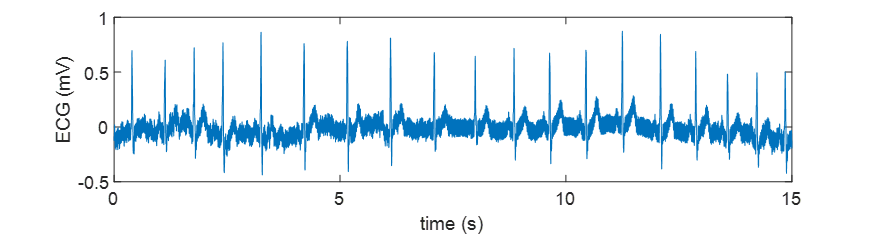 

**Detail:**

 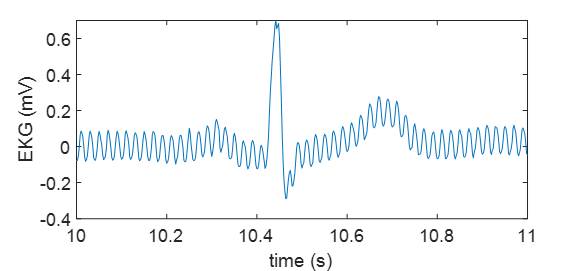

EKG signál zobrazuje elektrickou aktivitu srdce. Špičky v signálu (R-špičky) odpovídají kontrakci komor a vypuzení krve. Po přiblížení však vidíme téměř "harmonickou" složku superponovanou na signálu. Jedná se o síťové rušení $50$ Hz (např. v USA by byla $60$ Hz).

**Vykreslete EKG signál do grafu, připravte si figure(1) se subplot 5x1:**

N=length(EKG);
t= 0:1/fs:N*1/fs-1/fs;       % t=...
figure(1)
set(gcf, 'Position', [0 0 800 700]);
subplot(5,1,1)
plot(t, EKG)
axis tight
xlabel("čas [s]")
ylabel("EKG [mV]")

Spočítejte komplexní spektrum EKG signálu, označenou např. $S\left\lbrack f_k \right\rbrack \ldotp$ Zobrazte absolutní spektrum $\left|S\left\lbrack f_k \right\rbrack \right|$, nezapomeňte spektrálním čarám přiřadit odpovídající frekvence $f_k$ (frekvenční osu).

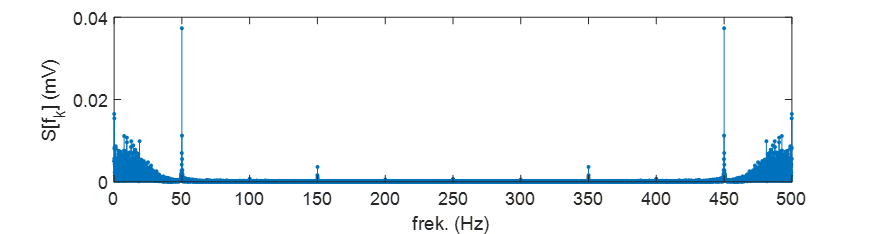

**Doplňte:**

S = 1/N*fft(EKG);% S=...; komplexní spektrum
F = linspace(0,fs,N);     % F=...; frekvenční osa
subplot(5,1,2)
set(gcf, 'Position', [0 0 800 700]);
stem(F,abs(S),'.') % zobrazení absolutního spektra
axis tight
xlabel("f [Hz]")
ylabel("|S| [mV]")


V absolutním spektru signálu si povšimněte, které frekvence nesou informaci ("nenulové" spektrální čáry). Pro EKG jsou to frekvence mezi 0-45 Hz. Výrazné špičky, zejména pak 50 Hz, méně pak na 100, 150, ... Hz odpovídají síťovému rušení a jeho vyšším harmonickým složkám, které se naindukovalo na kabely vedoucí od snímacích elektrod. Opět si připomeňme, že spektrum se zrcadlí kolem $\frac{f_s }{2}$, tj. zde 250 Hz.

Zobrazte absolutní spektrum v dB. Jelikož hodnoty mV v dB budou nabývat záporných hodnot, funkce `stem` pro zobrazení není vhodná. Spokojíme se se známou funkcí `plot`.  

 
$$X_{\textrm{dB}} \left\lbrack f_k \right\rbrack =10\cdot \log_{10} \left(\frac{1}{N}{\left|X\;\left\lbrack f_k \right\rbrack \right|}^2 \right)$$


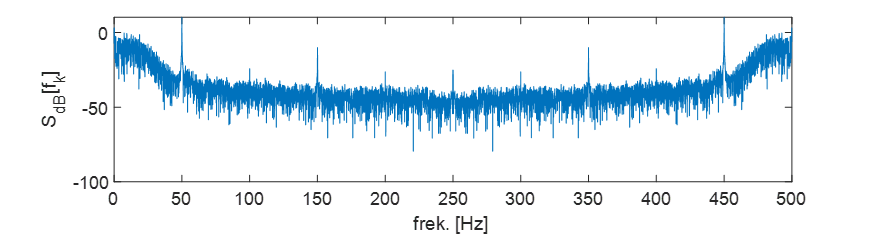

**Doplňte:**

SdB = 10*log10(1/N*abs(fft(EKG)).^2);        % SdB=... ; absolutní spektrum v dB 
subplot(5,1,3)
set(gcf, 'Position', [0 0 800 700]);
plot(F,SdB)
xlabel("frekv. [Hz]")
ylabel("S_{dB}(f_k) [dB]")


Logaritmické zobrazení magnitudy odhalí i menší špičky ve spektru, kde je síťové rušení jasně patrné i na 100, 150, 200 a 250 Hz. ,

#### **Nulování spektrálních čar**

Vizuálně jsme odhalily přítomnost síťového rušení v signálu (jak v časové rovině, tak i ve spektru). Najděme tedy spektrální čáry odpovídající rušení a odstraňme je z komplexního spektra vynulováním.

SN=S; % komplexní spektrum si zkopírujeme do SN, kde provedeme nulování

Budeme na frekvenční ose hledat pozici spektrálních  čar, které odpovídají hledaným násobkům 50 Hz a okolí ±1 Hz.

Tento postup musíme opakovat pro každou vyšší harmonickou 100±1, 150±1, ... , 250 ±1 Hz. Nežli výše popsaný kód kopírovat pro všechny frekvence, využijeme for cyklu:

**For cyklus nulující násobky** $m\times 50\pm 1\;\textrm{Hz}$:

Počet cyklů zvolte pro interval $\left\langle 50;\;\frac{f_s }{2}\right\rangle$ Hz. Můžete také využít pomocného vektoru do kterého si uložíte násobky 50 Hz až po $\frac{f_s }{2}$. Počet cyklů určíte délkou tohoto vektoru, nebo do `for` tento vektor přímo vložíte:

**Realizujte nulování ve for cyklu:**

f50=50:50:fs/2; 
for m=1:length(f50)
   SN(F >= f50(m)-1 & F<= f50(m)+1) = 0;            % výběr frekvence: f50(m)
end

f50=fs/2:50:fs-50; 
for m=1:length(f50)
   SN(F >= f50(m)-1 & F<= f50(m)+1) = 0;            % výběr frekvence: f50(m)
end

**Zobrazte spektrum po nulování. Vytvořte nový figure(2) se subplot 3x1:**

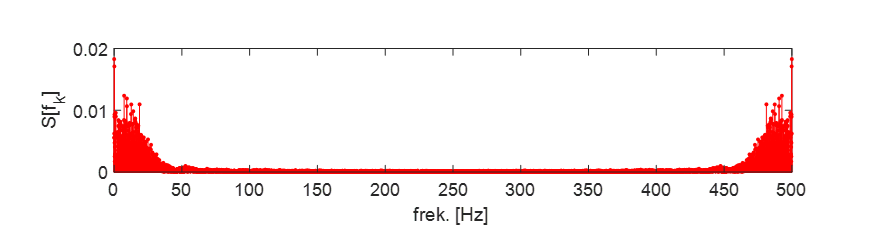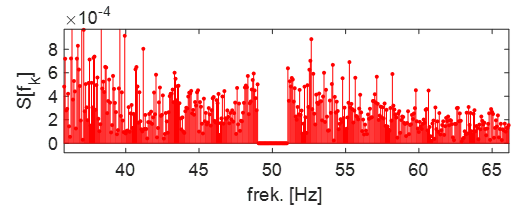

figure(2)
subplot(3,1,1)
stem(F, abs(SN),Marker=".",Color="r")        % stem
axis tight

Přibližte si spektrum a zkontrolujte, zda nulování provádíte správně na levé i pravé straně spektra ($0\;\textrm{až}\;\frac{f_s }{2}$, $\frac{f_s }{2}\;\textrm{až}\;f_s$).

#### **Rekonstrukce signálu:**

Z komplexního spektra s odstraněnými harmonickými složkami síťového rušení opět sestavíme signál. Použijeme inverzní rychlou Fourierovu transformaci (IFFT).

Připomeňme si, že pokud jsme normalizaci amplitudy $\frac{1}{N}$ prováděly na straně dopředné transformace. U zpětné proto musíme výsledek vynásobit $N$.

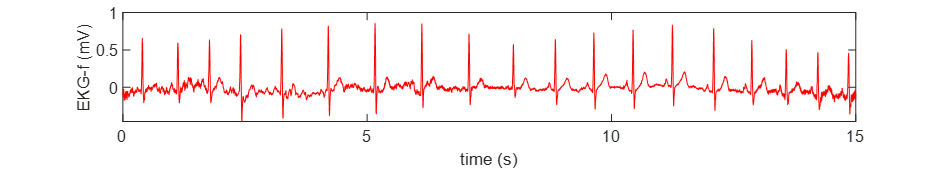

**Detail:**

 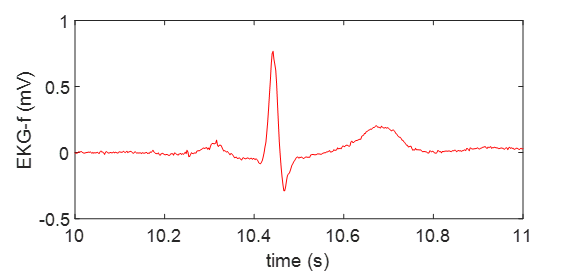

**Spočtěte IFFT a zobrazte filtrovaný signál:**

s = N*ifft(SN);
s = real(s);
figure 
set(gcf, 'Position', [0 0 800 700]);
subplot(3,1,1)
plot(t,s,Color='r')

**Subjektivně popište rozdíly mezi původním EKG signálem a výsledkem filtrace ve spektru:**

Lépe se dají rozpoznat detaily, protože se signál nemění příliš rychle. U původního EKG je signál tak rozkmitaný, že po vykreslení vypadá jako tlustá čára.